# a) Secular equilibrium:(ode45)

#  
$${^{144}Ce- {^{144}Pr$$


clc,clearvars,clf

%half lives, second
tHalfP=284.893*24*3600; 
tHalfD=17.29*60;   
%decay constants
lambdaP=log(2)/tHalfP; 
lambdaD=log(2)/tHalfD;
%Bateman equations
Bateman=@(t,N)[(-lambdaP*N(1));(lambdaP*N(1)-lambdaD*N(2))];
%using ode45 for numerical solution of Bateman equations
[t,N]=ode45(Bateman,[0 10000],[1/lambdaP 0]);
%activity
AP=lambdaP*N(:,1);  
AD=lambdaD*N(:,2); 

#### Plotting activity vs. time graph

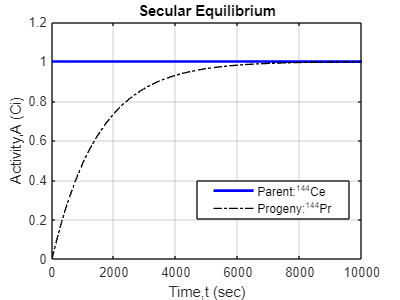

%parent activity vs. time graph
plot(t,AP,'b','linewidth',2) 
%axis scaling for better appearance
axis([0 10000 0 1.2]) 
hold on
%progeny activity vs. time graph
plot(t,AD,'k-.','linewidth',1) 
xlabel('Time,t (sec)')
ylabel('Activity,A (Ci)')
legend('Parent:^{144}Ce','Progeny:^{144}Pr')
title('Secular Equilibrium')
grid on

legend("Position", [0.49604,0.27152,0.37673,0.12731]) 